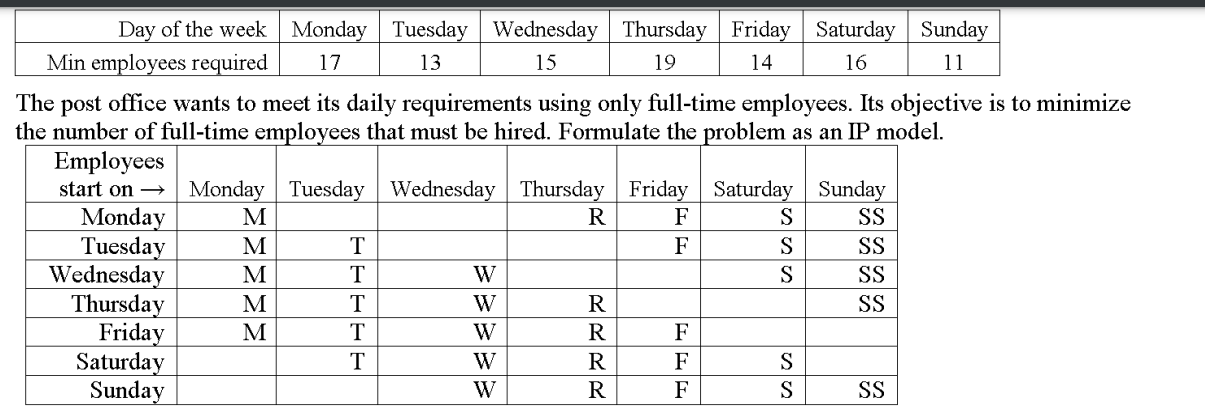

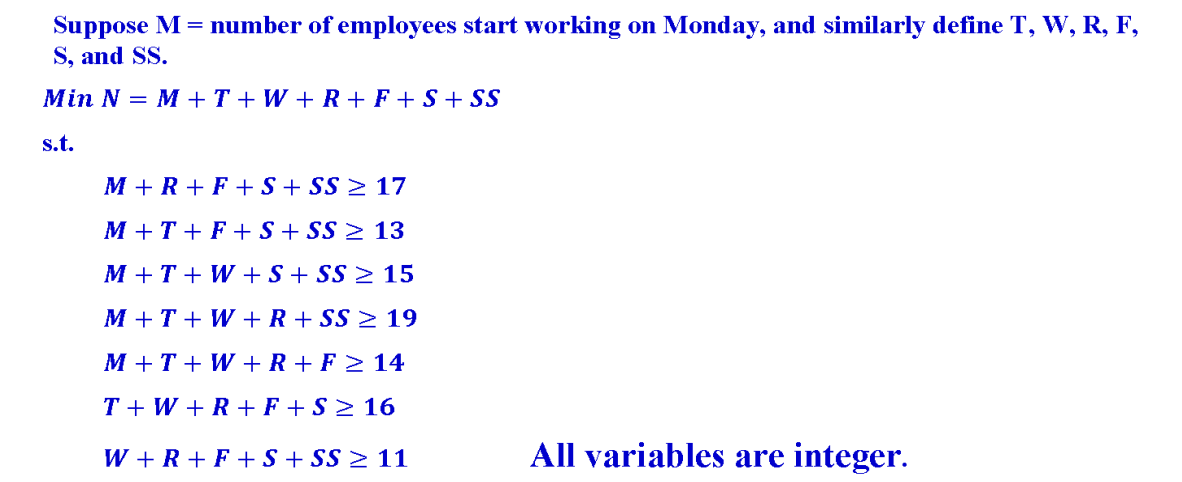

%https://ww2.mathworks.cn/help/optim/ug/intlinprog.html

f = [1;1;1;1;1;1;1];
N = 7;
intcon = 1:N;

A = [-1,0,0,-1,-1,-1,-1;
    -1,-1,0,0,-1,-1,-1;
    -1,-1,-1,0,0,-1,-1;
    -1,-1,-1,-1,0,0,-1;
    -1,-1,-1,-1,-1,0,0;
    0,-1,-1,-1,-1,-1,0;
    0,0,-1,-1,-1,-1,-1];
b = [-17;-13;-15;-19;-14;-16;-11];

lb = zeros(7,1);
ub = [Inf;Inf;Inf;Inf;Inf;Inf;Inf];

Aeq = [];
beq = [];
x = intlinprog(f,intcon,A,b,Aeq,beq,lb,ub)

LP:                Optimal objective value is 22.333333.                                            

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is 23.000000.                                                        
                   Relative gap is 0.00%.                                                          


找到最优解。

Intlinprog 在根节点处停止，因为目标值在最优值的间隙容差范围内，options.AbsoluteGapTolerance = 0。intcon 变量是容差范围内的整数，options.IntegerTolerance = 1e-05。



x =     0.0000
    4.0000
    2.0000
    8.0000
         0
    4.0000
    5.0000




%mathstat.dal.ca/~asarhan/MGSC1205/1205-SA4-10F.pdf




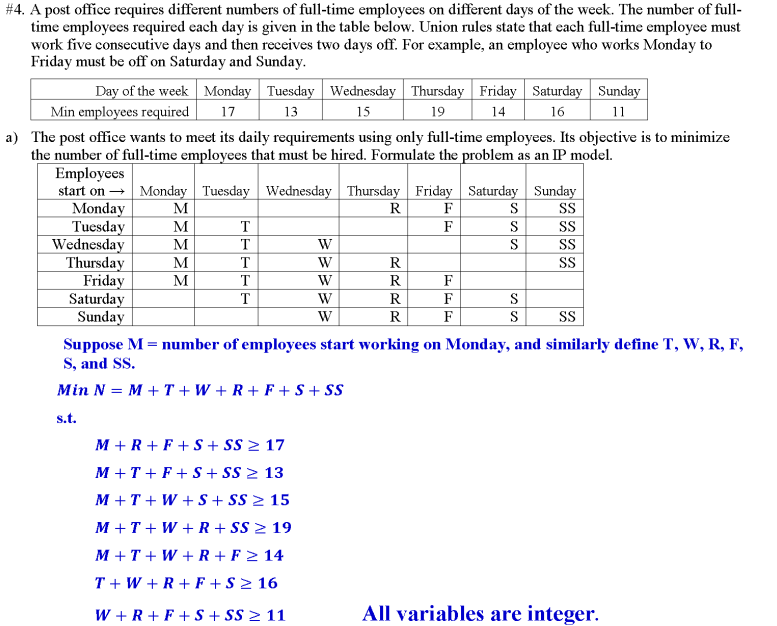

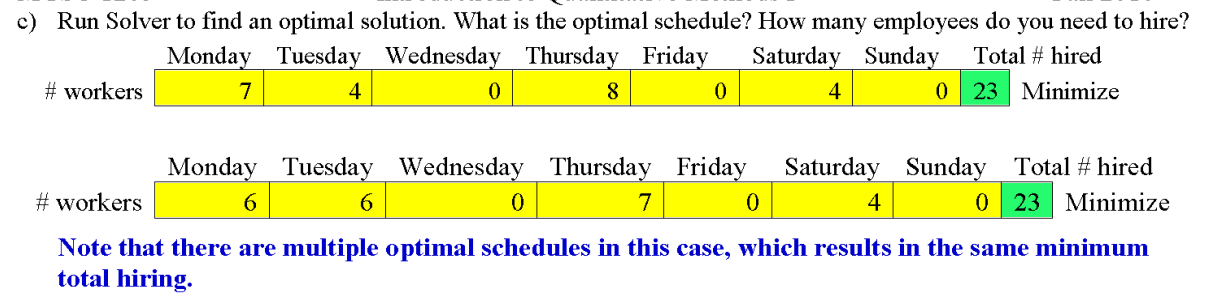

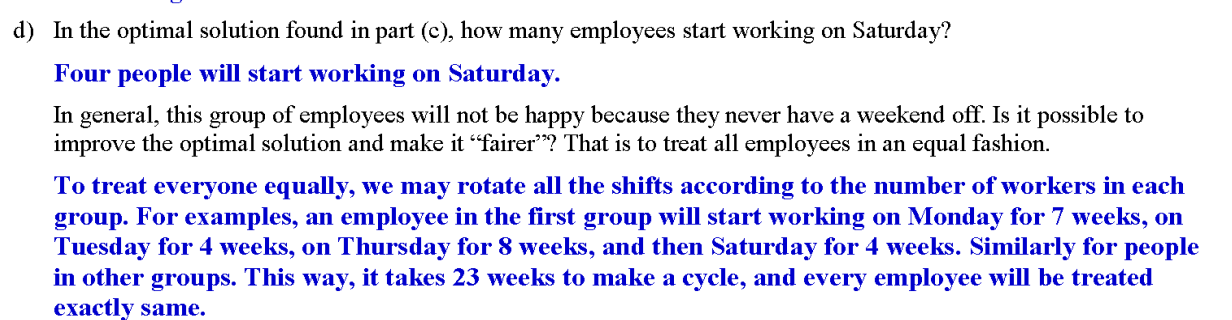

X = [1 1 1; 4 2 1; 9 3 1]

X =      1     1     1
     4     2     1
     9     3     1


Y = inv(X)

Y =     0.5000   -1.0000    0.5000
   -2.5000    4.0000   -1.5000
    3.0000   -3.0000    1.0000


Y*X

ans =     1.0000   -0.0000         0
         0    1.0000   -0.0000
   -0.0000         0    1.0000
